## Implementing Sigular Value Decomposition in MATLAB from Scratch

Importing image

building256 = cell2mat(struct2cell(load("building256.mat")));
X = building256/255;


Computing Co-Variance Matrix

C = X*X';

Computing Eigenvalues and Eigenvectors

[U,D] = eigs(C,5); 


Computing Right Singular Vectors

for i = 1:5
    V(:,:,i) = power(D(i,i),-0.5)*X'*U(:,i);
end


Reconstructing the image with different rank approximation

x(:,:,1) = sqrt(D(1,1))*U(:,1)*V(:,:,1)';
for i = 2:5
    for j = 2:i
        x(:,:,i) = x(:,:,i-1) + sqrt(D(j,j))*U(:,j)*V(:,:,j)';
    end
end

for i = 1:5
    error(i) = norm(x(:,:,i) - X,"fro")/norm(X,"fro");
    fprintf("Error of reconstruction in rank %d approximation is %f\n",i,error(i));
end

Error of reconstruction in rank 1 approximation is 0.174165
Error of reconstruction in rank 2 approximation is 0.114504
Error of reconstruction in rank 3 approximation is 0.082768
Error of reconstruction in rank 4 approximation is 0.071267
Error of reconstruction in rank 5 approximation is 0.064825


Ploting Reconstructed Images

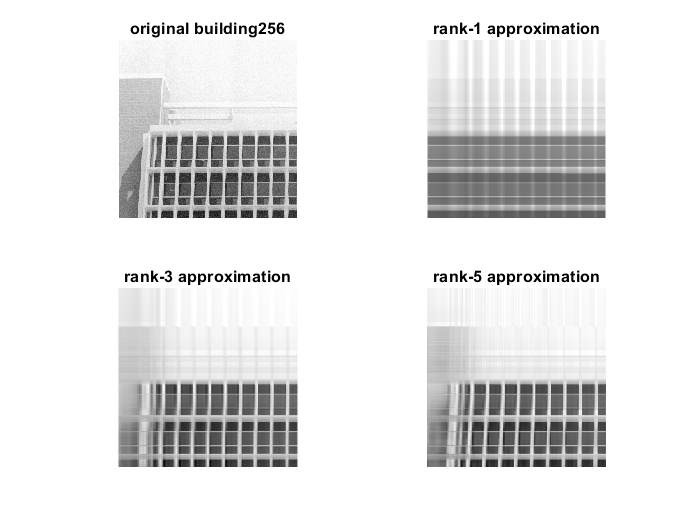

figure(1)
subplot(221)
imshow(X)
title("original building256")
subplot(222)
imshow(x(:,:,1))
title("rank-1 approximation")
subplot(223)
imshow(x(:,:,3))
title("rank-3 approximation")
subplot(224)
imshow(x(:,:,5))
title("rank-5 approximation")